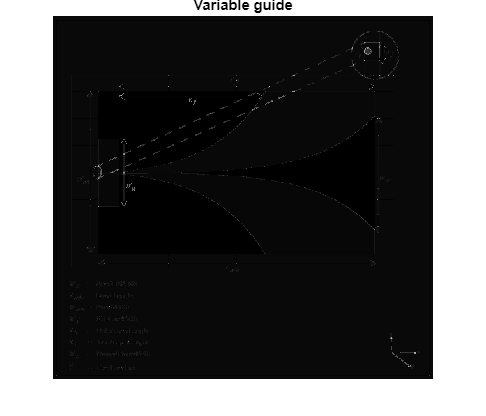

[url_img, map] = imread('https://www.mathworks.com/help/antenna/ref/vivaldiantipodal.png');
figure, imshow(url_img), title('Variable guide');

%frequency information
lowest_freq = 300e6;
highest_freq = 900e6;

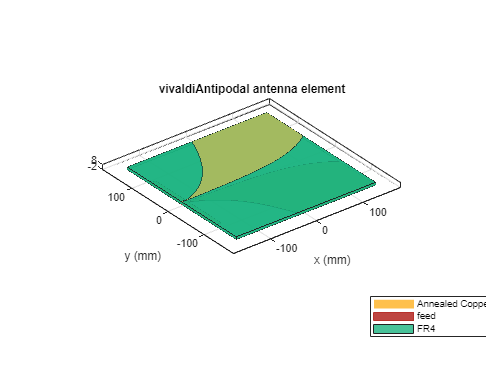

%generalized offset
offset = 50;

%variables that match with guide

%%x dimension
l = 0.3;
%%y dimension
w = 0.3;
%%z dimension
PCB_thickness = 5.08e-3;

%%ground plane width
ground_plane_width = w *.6;
ground_plane_length = 1.4e-2;

%%feed thickness
sma_connector_pin_diameter = 2e-3;
strip_line_width = sma_connector_pin_diameter;

inner_taper_length = l - ground_plane_length;
outer_taper_length = 0.125;

apature_width = w - 20e-2;

%variables that don't match with guide
opening_rate = 15;

%copper information
copper_thickness = 4.064e-4;
m = metal(Name = 'Annealed Copper', Conductivity=5.8001e07, Thickness = copper_thickness);

%dialectric information
d = dielectric('Name','FR4','EpsilonR',4.8,'LossTangent',0.026,'Thickness',PCB_thickness);

avi=vivaldiAntipodal( ...
    'BoardLength',l, ...
    'BoardWidth', w, ...
    'Height',PCB_thickness,...
    'OpeningRate',opening_rate, ...
    'GroundPlaneWidth',ground_plane_width,...
    'ApertureWidth',apature_width,...
    'StripLineWidth', sma_connector_pin_diameter,...
    'InnerTaperLength',inner_taper_length,...
    'OuterTaperLength',outer_taper_length,...
    'Conductor', m,...
    'Substrate', d);
figure, show(avi);

stacked_avi = pcbStack(avi);
%save avi.mat stacked_avi

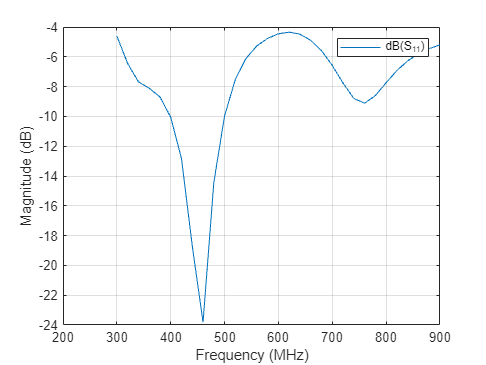

S = sparameters(stacked_avi,lowest_freq - offset:2e7:highest_freq + offset);
figure, rfplot(S);

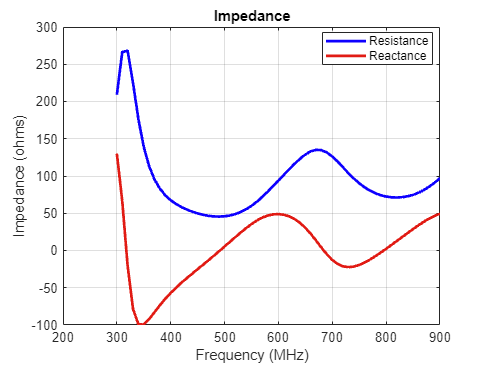

impedance(avi,lowest_freq - offset:1e7:highest_freq + offset);

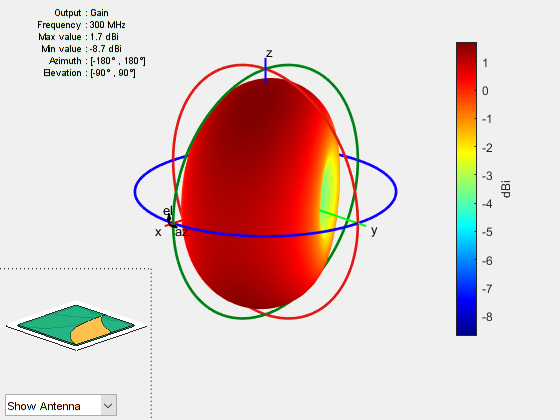

figure, pattern(avi, lowest_freq);

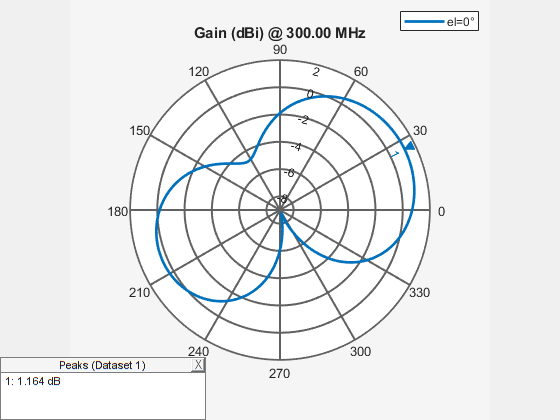

patternAzimuth(avi, lowest_freq);

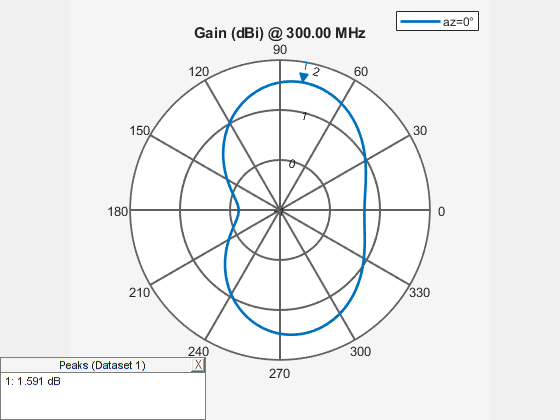

patternElevation(avi, lowest_freq);

Plot 1.600000e-02

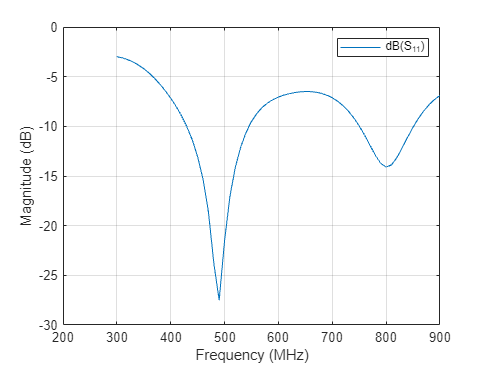

Plot 1.580000e-02

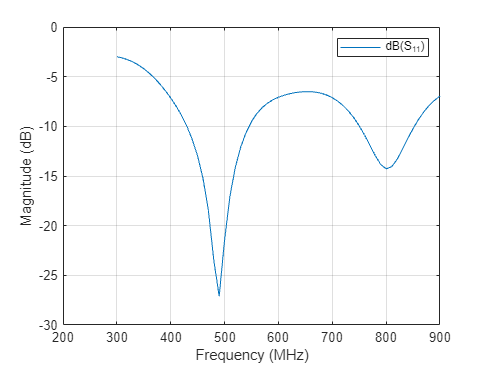

Plot 1.560000e-02

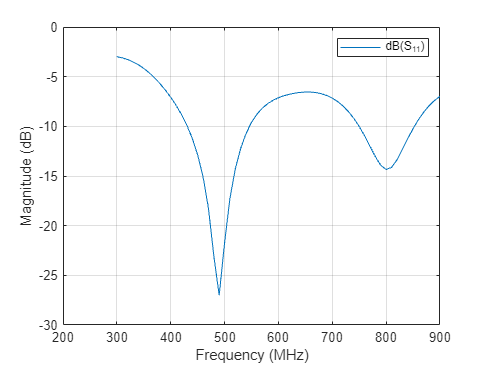

Plot 1.540000e-02

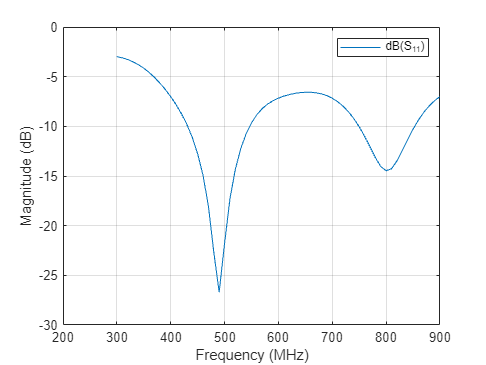

Plot 1.520000e-02

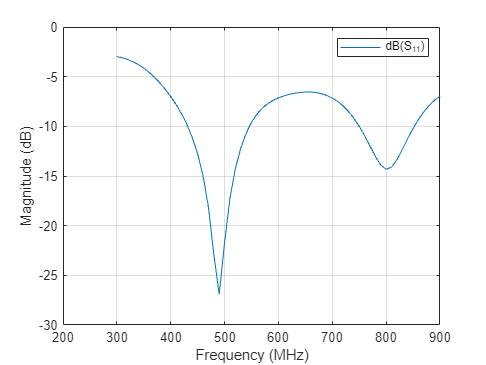

Plot 1.500000e-02

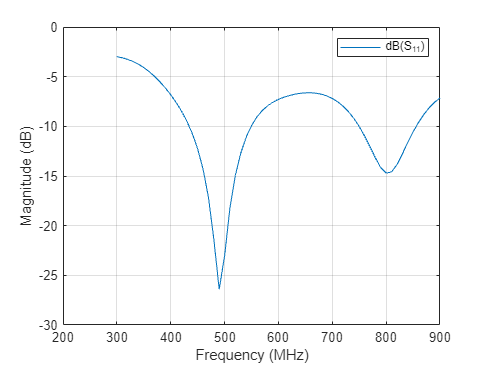

Plot 1.480000e-02

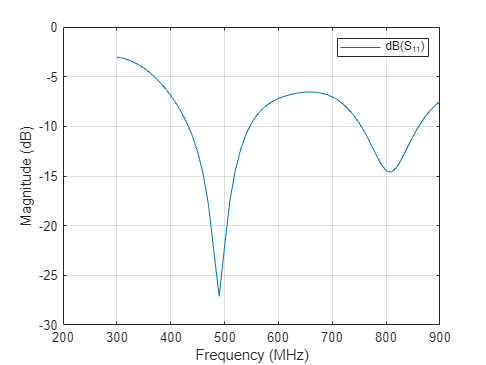

Plot 1.460000e-02

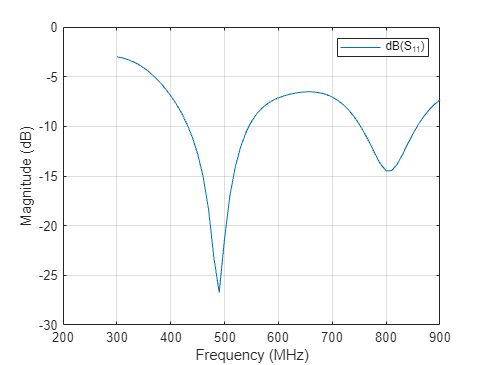

Plot 1.440000e-02

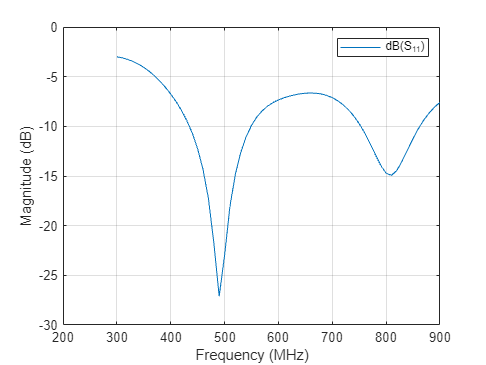

Plot 1.420000e-02

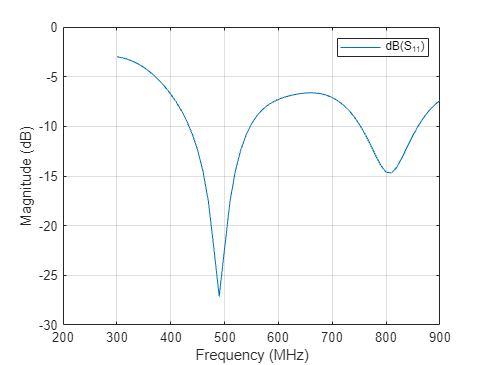

Plot 1.400000e-02

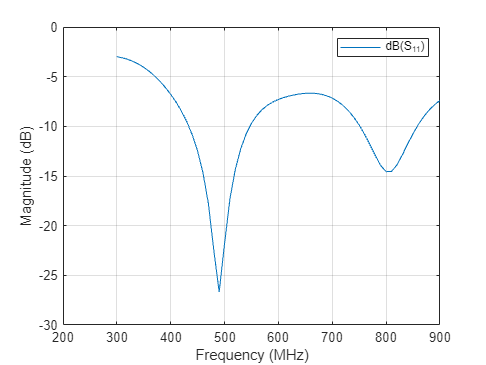

Plot 1.380000e-02

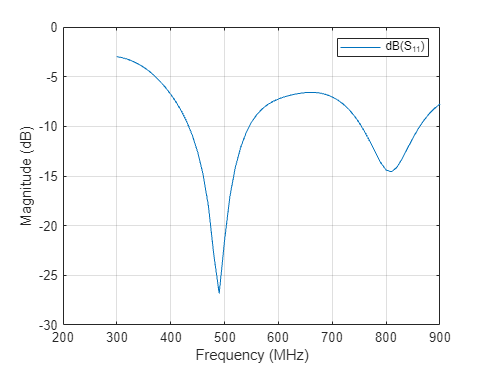

Plot 1.360000e-02

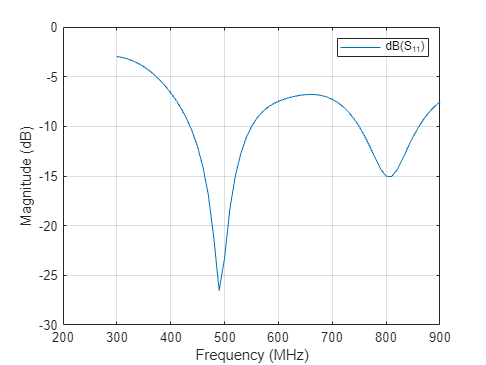

Plot 1.340000e-02

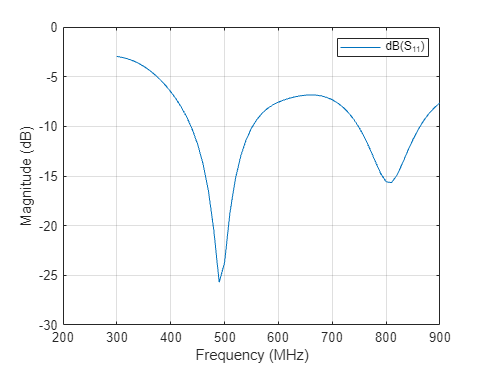

Plot 1.320000e-02

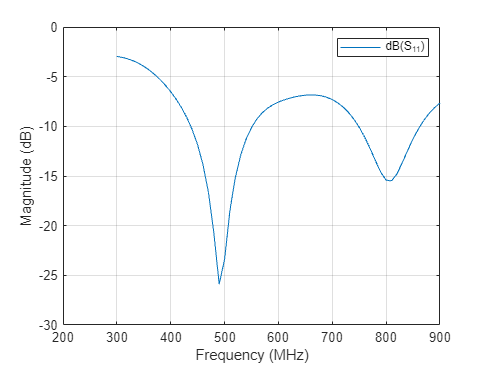

Plot 1.300000e-02

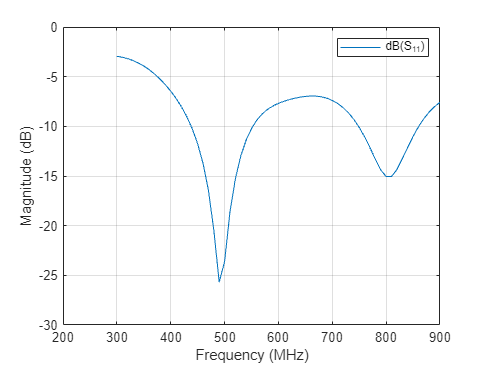

Plot 1.280000e-02

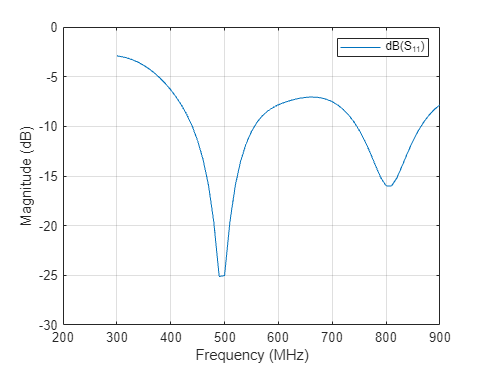

Plot 1.260000e-02

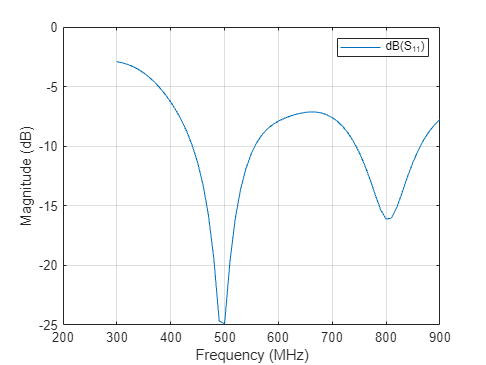

Plot 1.240000e-02

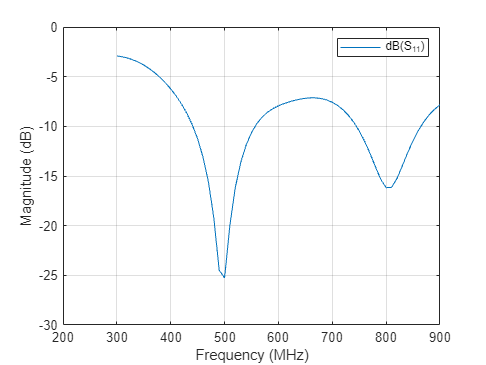

Plot 1.220000e-02

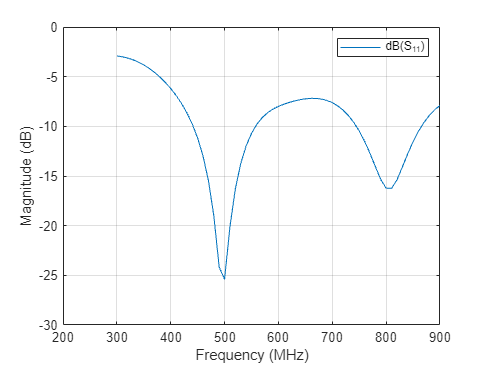

Plot 1.200000e-02

Error using vivaldiAntipodal/createGeometry (line 362)
The value specified for InnerTaperLength should be less than 0.288.

Error in vivaldiAntipodal/calculateMeshParams (line 320)
            createGeometry(obj);

Error in em.MeshGeometry/getMesh

Error in em.EmStructures/analyze

Error in 

for i = 1.6e-2:-2e-4:1.2e-2
    ground_plane_length = i;
    inner_taper_length = l - ground_plane_length;
    ava = vivaldiAntipodal( ...
    'BoardLength',l, ...
    'BoardWidth', w, ...
    'Height',PCB_thickness,...
    'OpeningRate',opening_rate, ...
    'GroundPlaneWidth',ground_plane_width,...
    'ApertureWidth',apature_width,...
    'StripLineWidth', sma_connector_pin_diameter,...
    'InnerTaperLength',inner_taper_length,...
    'OuterTaperLength',outer_taper_length,...
    'Conductor', m,...
    'Substrate', d);
    fprintf('Plot %d', i);
    figure, rfplot(sparameters(ava,lowest_freq - offset:1e7:highest_freq + offset));
end